# **PID Controller Design using Bode Diagram**

In reference to ***8-3 DESIGN OF PID CONTROLLERS WITH FREQUENCY-RESPONSE APPROACH,*** **Control Engineering, Ogata, 5th Ed**.

*marco.villafuerte.j@uni.pe*

## Goal

- Compare the unit-step and ramp-step response curves of a PID-Controlled system to the non-controlled outputs.

- Design a PID Controller using a frequency response (Bode Diagram) approach. The design requirements for the controller are:

- Desired Margin Phase, at least: ***Mphase = 60 °***

- Steady state error for a ramp-step input: ***ess =  0.1 ***

## System

The plant to be controlled is:


$$G_p(s) = \frac{s+100}{s^2+8s+65}$$


System outputs to Unit and Ramp step inputs:

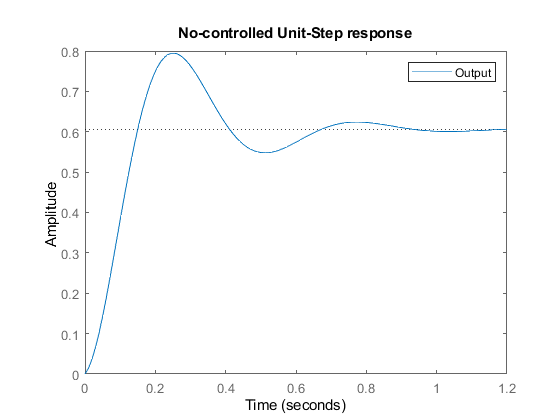

clear, clc, close all;
t = 0:0.01:2;
s = tf('s');           % s for Laplace operations

% Transfer Function and Feedback Loop
num = [1 100];
den = [1 8 65];
sysLA = tf(num,den);
sysLC = feedback(sysLA,1);

% No-Controlled system outputs
figure(1)             
step(sysLC)
title("No-controlled Unit-Step response")
legend('Output')

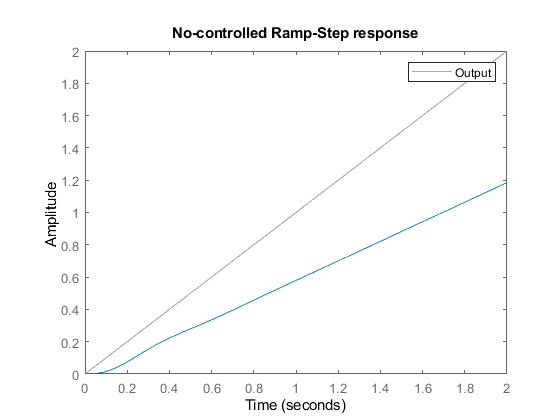


figure(2)              
lsim(sysLC,t,t)
title("No-controlled Ramp-Step response")
legend('Output')

PID controller to be implemented is: 


$$G_c(s)=\ \frac{K(as+1)(bs+1)}{s}$$


%{
Transfer function of the PID Controller:
Gc =  K(as+1)(bs+1)
     --------------
          s
%}

Design requirements:

% Design requirements:
Mfdeseado = 60;       % Desired margin phase(°)
ess       = 0.1;      % steady state error (to a ramp input)

% Original error constant Kv, to a ramp input
Kv = 1/ess;

Steady state error constant for the OPEN-Loop system:


$$\[
K_v = \lim_{s \to 0}(s*G_c*G_p)= \frac{1}{ess}
\]

\[
K_v = \lim_{s \to 0}(s*\frac{K(as+1)(bs+1)}{s}*\frac{s+100}{s^2+8s+65})= \frac{1}{ess}
\]

\[
K_v =  \frac{100K}{65} = \frac{1}{0.1} = 10
\]


\[
K = 6.5
\]$$


% K Gain of the controlled system
K= Kv/dcgain(sysLA);   

So:

- At this point, the requirement of ***ess = 0.1*** has been achieved.

### I - Controller

The first controller is just a  I - Controller. 


$$
\[
G_{tot} = G_c*G_p = \frac{K}{s}*\frac{s+100}{s^2+8s+65}
\]


\[
G_{tot} = G_c*G_p = \frac{6.5}{s}*\frac{s+100}{s^2+8s+65}
\]$$


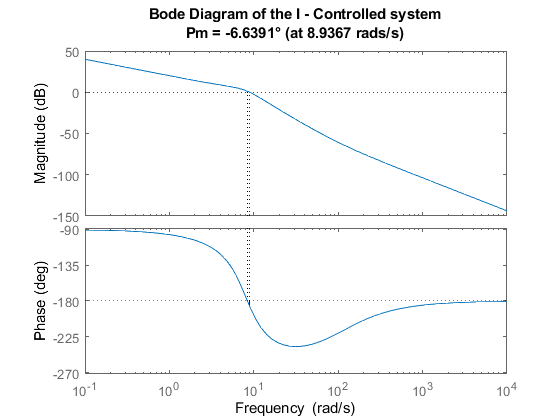

%{
Transfer function of the I Controller:
Gc =     K
     -------
         s
%}


%  Margin and cross frequency of the I Controlled system, Gc = K/s:
[MgActual, MfActual,Wcgain,Wcphase] = margin(K/s*sysLA);

% Bode diagram of the I Controlled system, Gc = K/s:
figure(3);
margin(K/s*sysLA);
txt = {'Bode Diagram of the I - Controlled system'; 
       ['Pm = ' num2str(MfActual) '° (at ' num2str(Wcphase) ' rads/s)'] };
title(txt);

Acording to the Bode Diagram, the current margin phase is Pm = - 6.64° at w = 8.94 rad/s. 

To get Pm = 60°, at the same frequency (or close) the two "*zeros*" of the originally designed controller will be used. 

#### *Adding a zero*

The first zero comes from* (as+1), *adding a 60° phase when w = 8.94 rad/s*. *

*(Why 60°? from here on, it's just a mater of trial and error)*


$$\[
as + 1 = 1 +ja\omega
\]

\[
\arctan(\frac{a\omega}{1}) = 60°
\]

\[
a = 0.1938
\]$$


% First ZERO of the controller (as+1) will add 60°
a = tan(deg2rad(60))/Wcphase;

### PI - Controller

The second controller is a  PI - Controller. 


$$
\[
G_{tot} = G_c*G_p = \frac{K(as+1)}{s}*\frac{s+100}{s^2+8s+65}
\]


\[
G_{tot} = G_c*G_p = \frac{6.5 (0.1938s+1)}{s}*\frac{s+100}{s^2+8s+65}
\]$$


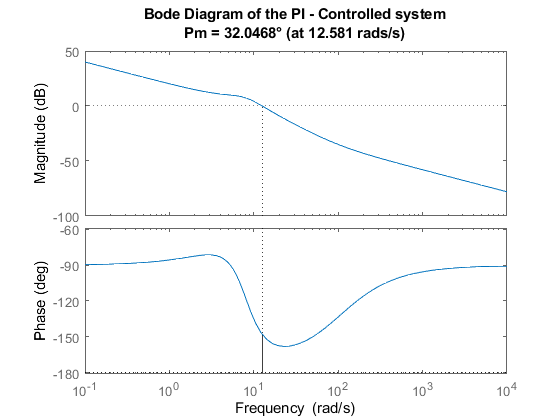

%{
Transfer function of the PI Controller:
Gc =  K(as+1)
     ----------
         s
%}


%  Margin and cross frequency of the PI Controlled system, Gc = K(as+1)/s:
[MgActual, MfActual,Wcgain,Wcphase] = margin(K*(a*s+1)/s*sysLA);

% Bode diagram of the PI Controlled system, Gc = K(as+1)/s:
figure(4)
margin(K*(a*s+1)/s*sysLA);
txt = {'Bode Diagram of the PI - Controlled system'; 
       ['Pm = ' num2str(MfActual) '° (at ' num2str(Wcphase) ' rads/s)'] };
title(txt);

Now, according to the Bode Diagram, the current margin phase is Pm = 32° at w = 12.6 rad/s. 

To important facts to point here: 

- A phase of 60° was added, but it only contributed to actual 38° (from -6° to 32°).

- The margin cross frequency went from 8.94 rad/s to 12.6 rad/s  

Again, to get a margin phase of at least Pm = 60°, at the same frequency (or close) another "*zero*" of the originally designed controller will be used. 

#### *Adding another zero*

The second zero comes from* (bs+1), *adding a 30° phase when w = 12.96 rad/s*. *

*(Why 30°? as the same as before, it's just a mater of trial and error)*


$$\[
bs + 1 = 1 +jb\omega
\]

\[
\arctan(\frac{b\omega}{1}) = 30°
\]

\[
b = 0.046
\]$$


% Second ZERO of the controller (bs+1) will add 30°
b = tan(deg2rad(30))/Wcphase;

%* Wcphase is now 12.6, because it was re-defined in the last script.


### Full PID - Controller

Finally, the last controller is a full PID - Controller that meets the design requirements:


$$
\[
G_{tot} = G_c*G_p = \frac{K(as+1)(bs+1)}{s}*\frac{s+100}{s^2+8s+65}
\]


\[
G_{tot} = G_c*G_p = \frac{6.5 (0.1938s+1)(0.046s+1)}{s}*\frac{s+100}{s^2+8s+65}
\]$$


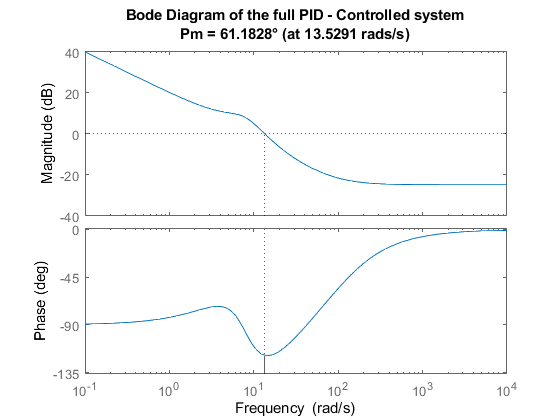

%{
Transfer function of the PID Controller:
Gc =  K(as+1)(bs+1)
     ---------------
         s
%}

%  Margin and cross frequency of the PID Controlled system, Gc = K(as+1)(bs+1)/s:
[MgActual, MfActual,Wcgain,Wcphase] = margin(K*(a*s+1)*(b*s+1)/s*sysLA);


% Bode diagram of the PID Controlled system, Gc = K(as+1)(bs+1)/s:
figure(5)
margin(K*(a*s+1)*(b*s+1)/s*sysLA);
txt = {'Bode Diagram of the full PID - Controlled system'; 
       ['Pm = ' num2str(MfActual) '° (at ' num2str(Wcphase) ' rads/s)'] };
title(txt);

According to the Bode Diagram, the current margin phase is Pm = 61.2° at w = 13.5 rad/s. 

So: 

- The required minimum phase of ***Pm = 60***° was achieved.

System outputs to Unit and Ramp step inputs:

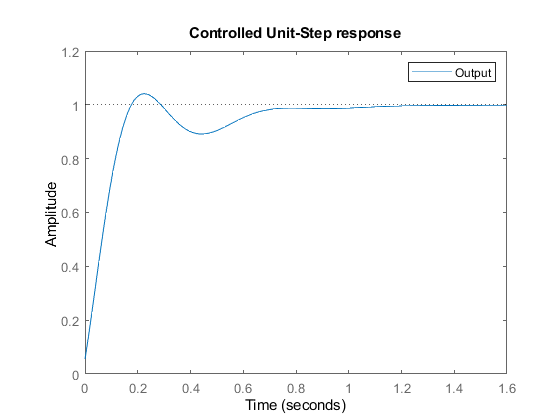

% Controller Transfer Function
Gc = K*(a*s+1)*(b*s+1)/s;

% Feedback of the full PID Controlled System
sysLCControlado = feedback(sysLA*Gc,1);

% Controlled system outputs
figure(6)             

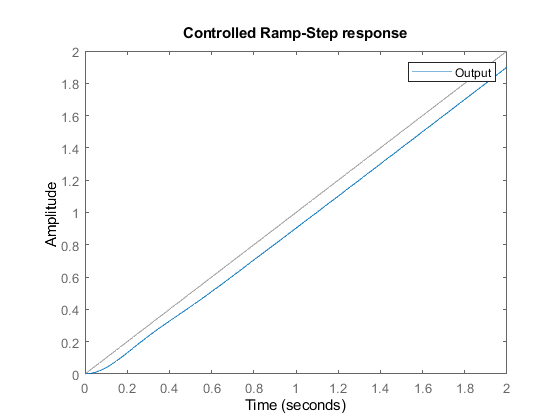

step(sysLCControlado)
title("Controlled Unit-Step response")
legend('Output')

figure(7)             

lsim(sysLCControlado,t,t)
title("Controlled Ramp-Step response")
legend('Output')

## Conclusions

- By comparing the unit-step and ramp-step response curves of a PID-Controlled system to the non-controlled outputs we realize that the PID Controller was succesfully designed, meeting both design requirements: 

- Desired Margin Phase, at least : ***Mphase = 61.2 °***

- Steady state error for a ramp-step input: ***ess =  0.1 ***